A = [
    [811802, 810901];
    [810901, 810001]
];
b = [901, 900]';
x = [1, -1]';

(a) $\text{cond}(A)=2.633\times 10^{12}$

cond(A, "inf")

ans = 2.6330e+12

(b) Note that $|\log_{10} \text{cond}(A)|=|\log_{10} 2.633\times 10^{12}|\approx 12$. In IEEE double precision, $\epsilon\approx 2.2\times 10^{-16}$, which means the entries in $A$ and $b$ are accurate to $|\log_{10} \epsilon\approx 16|$ decimal digits. Then using the rule of thumb, we know the entries is $\hat{x}$ will be accurate to about $16-12 = 4$ decimal digits.

(c)

format long
xa = A \ b;
disp(xa) 

   1.000027253771594
  -1.000027284053525



disp((xa - x) ./ x)

   1.0e-04 *

   0.272537715939603
   0.272840535251451



As we can see from the result, `A\b's error with respect to the accurate solution `$[1,-1]$ is about $2.7\times 10^{-5}$.

In (b), we estimated the accurate decimal digits to be $4$ using double float defintion and condition number of $A$, this verified our estimation. In fact,


$$\begin{array}{rl}\frac{\|\Delta \mathbf{x}\| / \|\mathbf{x}\|}{\|\Delta \mathbf{b}\| / \|\mathbf{b}\|}&= \frac{\|\Delta \mathbf{x}\| \|\mathbf{b}\|}{\|\mathbf{x}\| \|\Delta \mathbf{b}\|}\\&= \frac{\|A^{-1} \Delta \mathbf{b}\| \|A \mathbf{x}\|}{\|\mathbf{x}\| \|\Delta \mathbf{b}\|}\\&\le \frac{\|A^{-1}\| \|\Delta \mathbf{b}\| \|A\|  \|\mathbf{x}\|}{\|\mathbf{x}\| \|\Delta \mathbf{b}\|}& \\&= \|A^{-1}\| \|A\|\\&= \text{cond}(A)\end{array}$$


Hence


$$\frac{\|\Delta \mathbf{x}\|}{\|\mathbf{x}\|} \le \text{cond}(A)\frac{\|\Delta \mathbf{b}\|}{\|\mathbf{b}\|}$$


(d)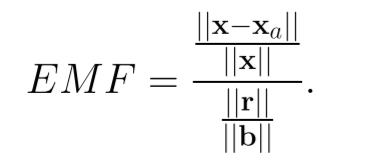

EMF = norm(x - xa, "inf") * norm(b, "inf") ...
    / (norm(x, "inf") * norm(b - A * xa, "inf"));
disp("EMF: " + EMF)

EMF: 211165779.9022


This $b$ doesn't maximize EMF, since if we keep $x$ identical to $[1,-1]$ and mulitply $b$ with a factor smaller than $1$, we shall get even larger EMF because of the expansion of difference of the norm of $b$ and $A$.

bp = b ./ 10;
xp = A \ bp;

EMF = norm(x - xp, "inf") * norm(bp, "inf") ...
    / (norm(x, "inf") * norm(bp - A * xp, "inf"));
disp("EMF: " + EMF)

EMF: 13917522435875.19
